**ENGN1930B Lab1**

**Instructor: Dr. Jonghwan Lee**

**Name: Kuan-Min Lee**

**(a)**

In this part of the experiment, the symbolic computation is implemented to computate function of z_foc.

To start with this, the symbolic computation is first implemented: 

clear all

syms z_src z_len f z positive % define z_src, z_len, and f as paratmeter
syms x_samp theta_samp positive % define the paramters and key variables for the function

assume(z_src>f)

rIn=[x_samp theta_samp]'; % define input light ray

Next, the RTM for air between the source and the first lens, first lens, air between the first and second lens, second lens, and the air after the second lens will be defined:

RTM_air_src_first=[1 z_src;0 1]; % RTM for air between the source and the first lens
RTM_first_lens=[1 0;-1/f 1]; % RTM for first lens
RTM_air_first_second=[1 z_len;0 1]; % RTM for air between the first and second lens
RTM_second_lens=[1 0;-1/f 1]; % RTM for second lens
RTM_air_second=[1 z;0 1]; % RTM for air after the second lens
RTM_sys=RTM_air_second*RTM_second_lens*RTM_air_first_second*RTM_first_lens*RTM_air_src_first; % RTM for the entire system

Next, we define the output light ray:

rOut=RTM_sys*rIn;

Then, we define the output function for x:

xOut(z,theta_samp,z_src,z_len,f,x_samp)=rOut(1);
xOutConc(z,z_src,z_len,f,x_samp)=xOut(z,0.1,z_src,z_len,f,0) % define the x difference function

$$xOutConc(z, z\_src, z\_len, f, x\_samp) = \frac{z}{10}-\frac{z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)}{10}-\frac{z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{10}$$

zsol(z_src,z_len,f)=solve(xOutConc==0,z) % solve for z (z_foc)

$$zsol(z\_src, z\_len, f) = \frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}$$

To comfirm the result from previous computation, a light source at position of x_samp, and angle of 0 and -0.1 rad is implemented. And the point where the light ray with these two different angles is observed:

xOut(z,theta_samp,z_src,z_len,f,x_samp)=rOut(1);
xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_src,z_len,f,x_samp/2)-xOut(z,-0.1,z_src,z_len,f,x_samp/2) % define the x difference function

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{z}{10}-\frac{z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)}{10}-\frac{z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{10}$$

zsol(z_src,z_len,f)=solve(xOutDiff==0,z) % solve for z (z_foc)

$$zsol(z\_src, z\_len, f) = \frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}$$

From the above the result, it can be seen that the results from the two are identical.

**(b):**

In this section, the magnification between the image on the focal plane and the original light source is observed.

To get the magnification ratio, x_foc needs computed:

x_foc=xOut(zsol(z_src,z_len,f),theta_samp,z_src,z_len,f,x_samp)

$$x\_foc = \begin{array}{l} x_{\mathrm{samp}}\,\sigma_{1}+\theta_{\mathrm{samp}}\,\left(\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}-z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)+z_{\mathrm{src}}\,\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)-\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}}{f}-\sigma_{2}+1\\ \sigma_{2}=\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)} \end{array}$$

Next, to get the maginfication ratio, it needs to be divided by the original x of light source:

m=x_foc/x_samp

$$m = \begin{array}{l} \frac{x_{\mathrm{samp}}\,\sigma_{1}+\theta_{\mathrm{samp}}\,\left(\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}-z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)+z_{\mathrm{src}}\,\sigma_{1}\right)}{x_{\mathrm{samp}}}\\ \mathrm{where}\\ \sigma_{1}=\frac{z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)-\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}}}{f}-\sigma_{2}+1\\ \sigma_{2}=\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)} \end{array}$$

**(c):**

For this portion of the experiment, the relative value of magnification will be computed. 

To start with this portion, the zrel_src and zrel_foc is setup:

zrel_src=z_src/f; % set up z_rel_src
zrel_foc=zsol(z_src,z_len,f)/f % compute z_rel_foc function

$$zrel\_foc = \frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)}$$

x_foc=xOut(zrel_foc,theta_samp,zrel_src,z_len,f,x_samp)

$$x\_foc = \begin{array}{l} \theta_{\mathrm{samp}}\,\left(\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)}-z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)+\frac{z_{\mathrm{src}}\,\sigma_{1}}{f}\right)+x_{\mathrm{samp}}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{z_{\mathrm{len}}\,\left(\sigma_{2}-1\right)-\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)}}{f}-\sigma_{2}+1\\ \sigma_{2}=\frac{f^{2}\,z_{\mathrm{len}}+f^{2}\,z_{\mathrm{src}}-f\,z_{\mathrm{len}}\,z_{\mathrm{src}}}{f^{2}\,\left(f\,z_{\mathrm{len}}+2\,f\,z_{\mathrm{src}}-z_{\mathrm{len}}\,z_{\mathrm{src}}-f^{2}\right)} \end{array}$$

**(d):**

For this portion of the expeirment, the effect of the deviation of LED position on the image formation will be observed.

To start with this problem, the z_rel_src values are set to be between 0.8 to 1.2, the focal point value is set to be 40 mm, and the z_len is set to be 1-, 2-, 3-, and 4-time the focal point value:

z_rel_src=0.8:0.05:1.2; % setup z_rel_src value
f1=40e3; % setup focal point length (40mm)
z_len_fact=[1 2 3 4]; % setup factor for z_len
num_z_rel_src=numel(z_rel_src);
num_fact=numel(z_len_fact);

Then, the setup for plotting z_rel_foc over z_rel_src will be setup:

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{24999\,z}{250000}-\frac{49999\,f\,\left(\frac{z}{40000}-1\right)}{500000}+\frac{2}{25}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{399983\,z}{4000000}-\frac{799983\,f\,\left(\frac{z}{40000}-1\right)}{8000000}+\frac{17}{200}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{199991\,z}{2000000}-\frac{399991\,f\,\left(\frac{z}{40000}-1\right)}{4000000}+\frac{9}{100}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{399981\,z}{4000000}-\frac{799981\,f\,\left(\frac{z}{40000}-1\right)}{8000000}+\frac{19}{200}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{19999\,z}{200000}-\frac{39999\,f\,\left(\frac{z}{40000}-1\right)}{400000}+\frac{1}{10}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{399979\,z}{4000000}-\frac{799979\,f\,\left(\frac{z}{40000}-1\right)}{8000000}+\frac{21}{200}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{199989\,z}{2000000}-\frac{399989\,f\,\left(\frac{z}{40000}-1\right)}{4000000}+\frac{11}{100}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{399977\,z}{4000000}-\frac{799977\,f\,\left(\frac{z}{40000}-1\right)}{8000000}+\frac{23}{200}$$

$$ans = -\theta_{\mathrm{samp}}\,\left(z_{\mathrm{src}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)-z+z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)\right)-x_{\mathrm{samp}}\,\left(\frac{z}{f}+\frac{z-z_{\mathrm{len}}\,\left(\frac{z}{f}-1\right)}{f}-1\right)$$

$$xOutDiff(z, z\_src, z\_len, f, x\_samp) = \frac{49997\,z}{500000}-\frac{99997\,f\,\left(\frac{z}{40000}-1\right)}{1000000}+\frac{3}{25}$$

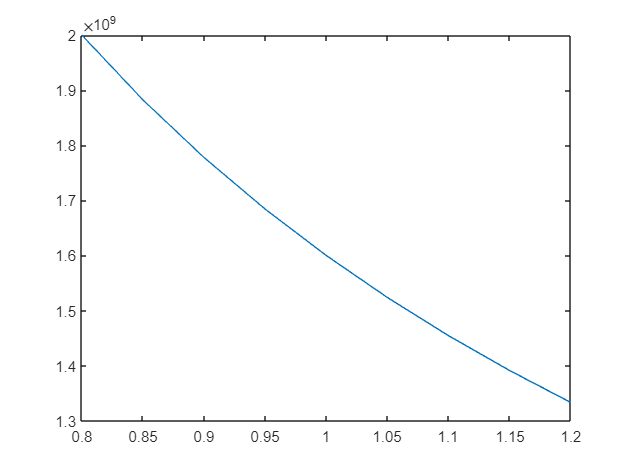

Error using line
Not enough input arguments.

for i_fact=1:num_fact
    figure(i_fact);
    zout=zeros(2,num_z_rel_src);
    for i_z_rel_src=1:num_z_rel_src
        % grab out parameters
        z_rel_src1=z_rel_src(i_z_rel_src);
        z_len1=z_len_fact(i_fact)*f;
        xOut(z,theta_samp,z_src,z_len,f,x_samp)
        xOutDiff(z,z_src,z_len,f,x_samp)=xOut(z,0,z_rel_src1,z_len1,f1,x_samp/2)-xOut(z,-0.1,z_rel_src1,z_len1,f1,x_samp/2) % define the x difference function
        zsol(z_src,z_len,f)=solve(xOutDiff==0,z); % solve for z (z_foc)
        zout(1,i_z_rel_src)=zsol(z_rel_src1,z_len1,f1);
        zout(2,i_z_rel_src)=z_rel_src1;
    end
    plot(z_rel_src,zout(1,:));
    line(z_rel_src)
    line(z_rel_src,zeros(size(z_rel_src)),'color','k','linewidth',2);  % optical axis
    line([0 0], get(gca,'ylim'),'color','k','linewidth',2);  % lens
    axis image;  % set x and z scales identical
    grid on;
    xlabel('z [mm]');
    ylabel('x [mm]');
end